clear; clc; close all

Load a test image.

% impath = ".\data\spiral\training\parkinson";
impath = ".\data\PD_DRAWINGS\nc"; % Hemen aldatu "nc" eta "pd" artean.

nc_names = struct2cell(dir(".\data\PD_drawings\nc"));
nc_names = nc_names(1,:); nc_names = nc_names(3:end);
pd_names = struct2cell(dir(".\data\PD_drawings\pd"));
pd_names = pd_names(1,:); pd_names = pd_names(3:end);

Zein irudi kargatu nahi dozu? Lehenengoa? Hogeigarrena? Aldatu "k" horren arabera.

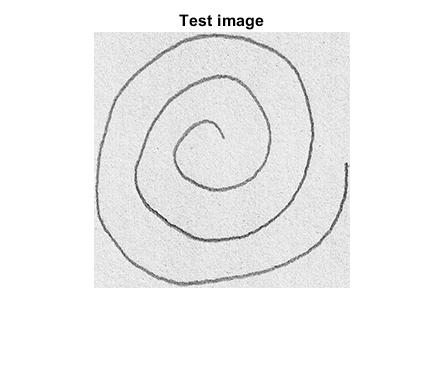

k = 45; 
imname = nc_names{k}; % impath-en "nc" jarri badozu, hemen jarri nc_names, eta ez pd_names. Alderantziz, bardin.
im = im2double(rgb2gray(imread(impath + '\' + imname)));
if size(im, 1) > 500
    im = imresize(im, 0.25); % Irudi sintetikoak resize!!!
end
imshow(im, []); title('Test image')

[M, N] = size(im);

View image histogram

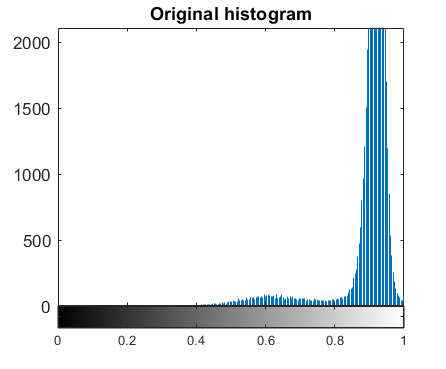

imhist(im);
title('Original histogram');

Apply Otsu's method thresholding to get the ROI of the stroke. Isolate the stroke.

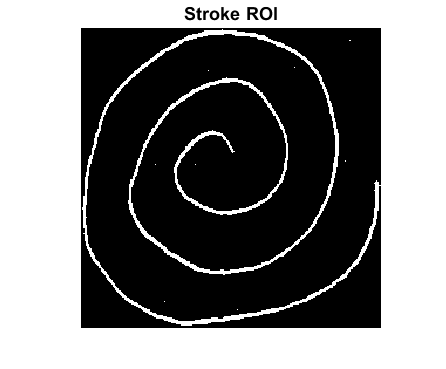

T = graythresh(im);
ROI = im < T;
ROI = imclose(ROI, strel("square", 4));
imshow(ROI); title('Stroke ROI')

Delete elements with less than 100 pixels. (Sometimes, there are numbers in our synthetic spirals. My bad.)

ROI = bwareaopen(ROI, 100, 8);

Thin the image as much as possible and prune it.

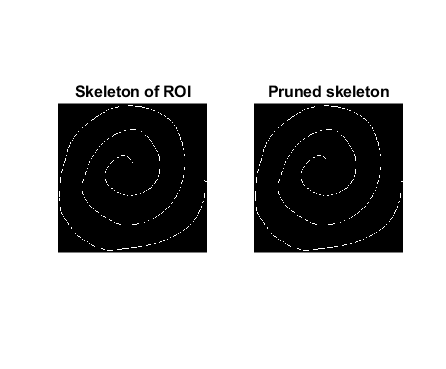

skel_im = bwmorph(ROI, 'thin', Inf);
subplot(121);imshow(skel_im); title('Skeleton of ROI')

% Prune the skeleton
pruned_skel_im = bwmorph(skel_im, 'spur', 10);

N_pruned_pixels = sum(sum(xor(pruned_skel_im, skel_im))); % This could be a feature

% Then we try not to break the spiral by closing it (to connect possibly
% broken segments)
pruned_skel_im = imclose(pruned_skel_im, strel("square", 3));
% Remove the salt again (it can appear after pruning)
pruned_skel_im = bwareaopen(pruned_skel_im, 10);

% Visualize
subplot(122);imshow(pruned_skel_im); title('Pruned skeleton')

Start region growing.

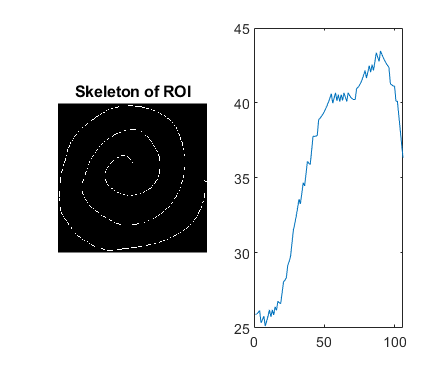

ROI = pruned_skel_im;  % We rename our Region of Interest

% Get the biggest element
bigblob = bwareafilt(ROI, 1);
% Get the points that belong to it.
points = bwboundaries(bigblob);
centroid = regionprops(bigblob, 'Centroid');


points = points{1};
% Default, no spiral tracking contour signature.
contourSig_def = sqrt((points(:,1)-centroid.Centroid(:,1)).^2 + ...
    (points(:,2)-centroid.Centroid(:,2)).^2);
% Save X & Y points in separate arrays
ylocs = points(:,1); xlocs = points(:,2);

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% This is my function for spiral following. 
% It is quite error prone... We tried our best.

% First we need to get one of the starting points. Hit or miss. 
% No matter which one we take and the order of growing, 
% because we will look at the spectral information of the signal.

% Find endpoints and get the outermost one (no particular reason, 
% just to be consistent)

hits = bwmorph(bigblob, 'endpoints'); [endpy, endpx] = find(hits);

% Measure euclidean distance to center and take closest (closest point
% from center)
[M, N] = size(im);
C = round(0.5*[M, N]);
dists = sqrt((endpy-C(1)).^2 + (endpx-C(2)).^2); [~, closest] = min(dists);
Y_init = endpy(closest); X_init = endpx(closest);
target_im = zeros(M,N); target_im(Y_init, X_init) = 1;
dilater = strel('square', 3);

Xk = target_im;
canv_n = bigblob;
canv_n = padarray(canv_n, [1,1], 0);
[M, N] = size(im);
pointy = Y_init + 1; pointx = X_init + 1; % Add 1 because we padded !!!

endp_temp = [0,0,0;0,1,0;0,1,0];
p = 0; ci = 1; ck = 1;
while ~isequal(canv_n, zeros(size(canv_n))) || ck > 5
    canv_n(pointy, pointx) = 0;
    p = find(canv_n(pointy-1:pointy+1, pointx-1:pointx+1));
    if isempty(p)
        break;
    end
    p = p(1);

    switch p
        case 1
            pointy = pointy - 1;
            pointx = pointx - 1;
        case 2
            pointx = pointx - 1;
        case 3
            pointy = pointy + 1;
            pointx = pointx - 1;
        case 4
            pointy = pointy - 1;
        case 6
            pointy = pointy + 1;
        case 7
            pointy = pointy - 1;
            pointx = pointx + 1;
        case 8
            pointx = pointx + 1;
        case 9
            pointy = pointy + 1;
            pointx = pointx + 1;
    end
    X_pts(ck, ci) = pointx;
    Y_pts(ck, ci) = pointy;

    ci = ci + 1;
end

% delete possible small stuff (it will appear and haunt your dreams)
canv_n = bwareaopen(canv_n, 10, 8);
% Compute contour signature
contourSig_mine = sqrt((X_pts-centroid.Centroid(1)).^2 + (Y_pts-centroid.Centroid(2)).^2);

spec = fft(contourSig_mine, length(contourSig_mine));
half = round(length(spec) / 2);
spec = spec(1:half);
spec = abs(spec);
% Ratio of high frequency power accounting for fast varying coordinates, tremor of
% the hand, respect to whole spectrum.
th = round(length(spec) / 100);
HFP = sum(spec(th:end)) / sum(spec);

% New feature: distance from centroid of figure spiral's inner endpoint. If
% the spiral is properly drawn, this should be minimized. If not, it gets
% bigger. (Hypothesis!). Let's call it IECD
% (inner-endpoint-centroid-distance) %%% NEEDS TO BE DISCUSSED!
% IECD = sqrt((centroid.Centroid(1)-X_init).^2 + (centroid.Centroid(2)-Y_init).^2);


% Rangayyan's ff number just in case it turns out to be supa good.
ff = fourier_descriptors(X_pts, Y_pts);

plot(contourSig_mine)

Gauze bat. Espiralen shape contourra atarateko hau nik uste ya finished dauela. Spectroko zein parametro hartu eztakit ondo. Spectral power espektruko %1 etik %100era hartu dot, 0%-1% artean dauena espiralaren basea dala hipotetizatzen. Ia zer deritzozun.

Gero beste feature bat, goian dago azalduta --> IECD. Ia zer deritzozun, zeozerekiko normalizatu beharko litzatekeala uste dot. Bueno, esangostezu !!!

function ff = fourier_descriptors(xlocs, ylocs)
N = length(xlocs);
% Preallocate S for speed
S = zeros(1, N);
for cK = 1:N
    S(cK) = xlocs(cK) + 1j * ylocs(cK);
end

% Compute spectrum
Z = fft(S, N);
Z(1) = 0; % Remove centroid, not useful.

% Normalize
Zn = Z / abs(Z(2) + Z(end));

% Get Rangayyan's Magic number "ff"
s_1 = 0; s_2 = 0;
for cI = 1:N/2-1
    s_1 = abs(Zn(cI+1)) / cI + abs(Zn(end-cI+1)) / cI + s_1; 
    s_2 = abs(Zn(cI+1)) + abs(Zn(end-cI+1)) + s_2;
end


ff = 1 - (s_1/s_2);
end
